# M4T1: Método de RK de 4o Orden

`Nombre: Daniel Alfredo Barreras Meraz`

`Matrícula: A01254805`

`Fecha: 30 de mayo de 2023`

## `Problema 2 a)`

El modelo del circuito RC mostrado en la figura puede ser determinado aplicando las leyes de Kirchoff. Este es $\frac{dy}{dt}+y=v(t)$. Suponga que el valor RC es 0.1 s. Use el método numérico de Runge Kutta para encontrar la respuesta libre para el caso en el que el voltaje aplicado es cero, y el voltaje inicial en el capacitor es y(0) = 2 V. Compara el resultado conla solución analítica: $y(t)=2e^{-10t}$ .

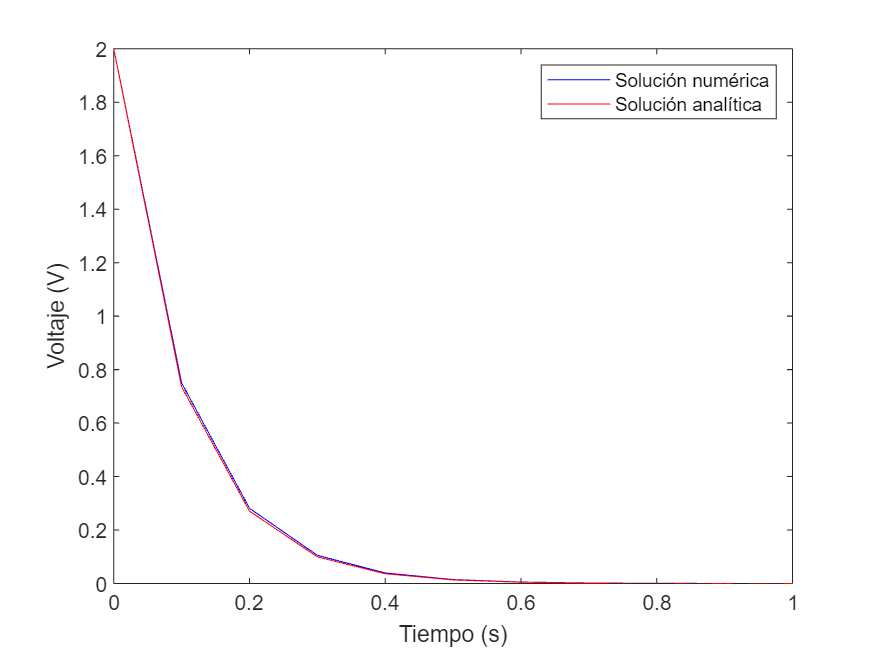

% Definir la función que representa la ecuación diferencial del circuito RC
R = 1; % Resistencia en ohmios
C = 0.1; % Capacitancia en faradios
f = @(t,y) -y/(R*C);

% Definir las condiciones iniciales y el intervalo de tiempo
t0 = 0; % Valor inicial del tiempo
tf = 1; % Valor final del tiempo
h = 0.1; % Tamaño del paso
tspan = [t0 tf]; % Intervalo de tiempo en segundos
y0 = 2; % Voltaje inicial 

% Llamar a la función rk4 para obtener la solución numérica
[t,y] = rk4(f,tspan,y0,h);

% Calcular la solución analítica
y_analitica = 2*exp(-10*t);

% Graficar los resultados
plot(t,y,'b',t,y_analitica,'r')
legend('Solución numérica','Solución analítica')
xlabel('Tiempo (s)')
ylabel('Voltaje (V)')

## Problema 2 b)

Resuelve y grafica la solución de la siguiente ecuación.


$$10\frac{dy}{dt}+y=20+7\sin{2t}, y(0)=15$$


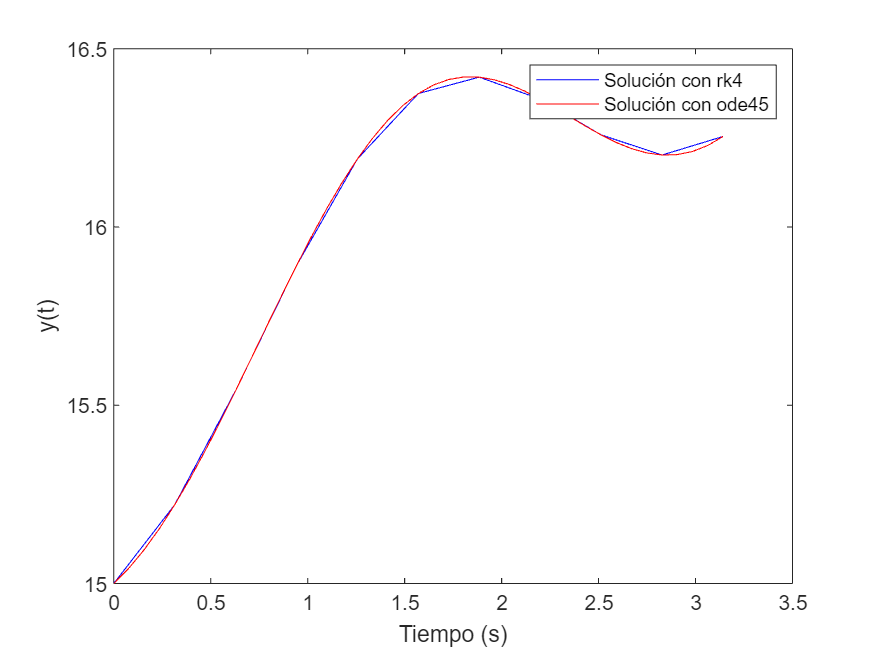

% Definir la función f que representa la ecuación diferencial
f = @(t,y) (20 + 7*sin(2*t) - y)/10;

% Definir las condiciones iniciales y el intervalo de tiempo
t0 = 0; % Valor inicial del ángulo en radianes
tf = pi; % Valor final del ángulo en radianes
n = 10; % Número de segmentos
tspan = [t0 tf]; % Intervalo de tiempo en segundos
y0 = 15; % Valor inicial de y

% Llamar a la función rk4 para obtener la solución numérica
h = (tf-t0)/n; % Tamaño del paso
[t_rk4,y_rk4] = rk4(f,tspan,y0,h);

% Llamar a la función ode45 para obtener la solución numérica
[t_ode45,y_ode45] = ode45(f,tspan,y0);

% Graficar los resultados
plot(t_rk4,y_rk4,'b',t_ode45,y_ode45,'r')
legend('Solución con rk4','Solución con ode45')
xlabel('Tiempo (s)')
ylabel('y(t)')

## Función que aplica el método de Runge-Kutta de 4º orden.

function [t,y] = rk4(eq,condicionInicial,intervalo,h)
    t = condicionInicial(1):h:condicionInicial(2);
    y = zeros(length(intervalo),length(t));
    y(:,1) = intervalo;
    for i = 1:length(t)-1
        k1 = eq(t(i),y(:,i));
        k2 = eq(t(i)+h/2,y(:,i)+h/2*k1);
        k3 = eq(t(i)+h/2,y(:,i)+h/2*k2);
        k4 = eq(t(i)+h,y(:,i)+h*k3);
        y(:,i+1) = y(:,i) + h/6*(k1+2*k2+2*k3+k4);
    end
end